# Confronto ideale e reale al crescere di Rp/Rm

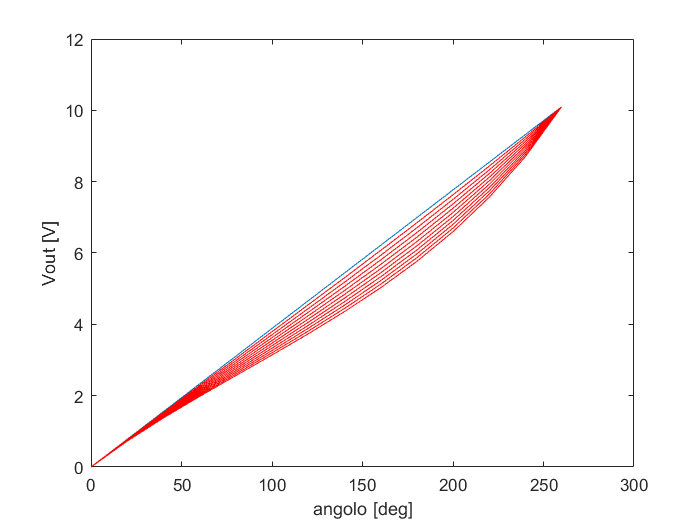

clc;
clear all;
close all;

V0 = 10.1; % Tensione di alimentazione
L = 260; % Angolo totale di escursione

theta = 0:20:260;

V = V0 * theta/L;

k = 0.1:0.1:1.0; % k = Rp/Rm

Vr = []; % conterra' le future tensioni reali al variare di k

figure
plot(theta, V);

% V = (V0 * theta/L) ./(1 + k(:,ii) * theta/L .* (1 - theta/L)) modello
% reale
hold on

for ii = 1:length(k)
    Vr = [Vr; (V0 * theta/L) ./(1 + k(:,ii) * theta/L .* (1 - theta/L))];
    plot(theta, Vr(ii,:), '-r')
end

hold off
xlabel('angolo [deg]');
ylabel('Vout [V]');

## OTTIMIZZAZIONE

DATI 2005

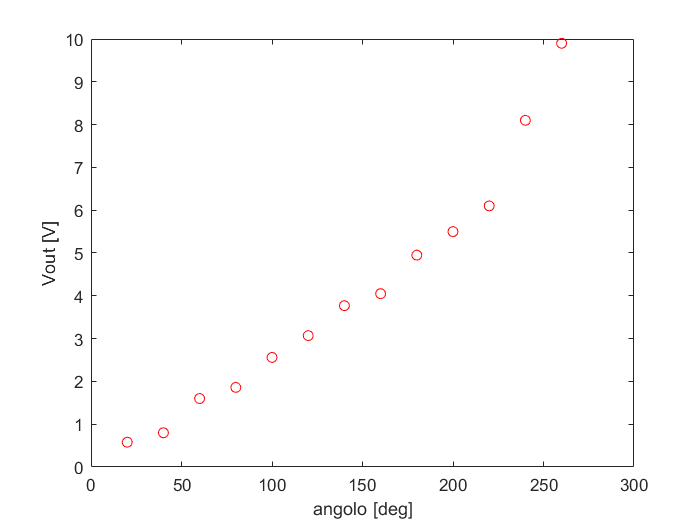

clc;
clear;
close all;

V0 = 10.1; % Tensione di alimentazione
L = 260; % Angolo totale di escursione

theta = [20   40   60   80   100  120  140  160  180  200  220  240  260];
Vout = [0.58 0.8  1.6  1.86 2.56 3.07 3.77 4.05 4.95 5.5  6.1  8.1  9.9]; 
    
% Plot
figure
plot(theta, Vout, 'or')
xlabel('angolo [deg]');
ylabel('Vout [V]');


y = Vout;

% V = V0 * x/L /(1+p*x/L*(1-x/L))
fun = @(p)((V0 * theta/L) ./(1+p*theta/L.*(1-theta/L))- y); %lo scarto

options = optimset('Algorithm','levenberg-marquardt', 'Display','iter', 'TolFun', 1e-20 );
x0 = 0.11;

k = lsqnonlin(fun,x0,[],[],options);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           2         27.2477            17.4         0.01
     1           4         2.23073            2.52        0.001        1.50384
     2           6        0.682423           0.198       0.0001       0.613201
     3           8        0.668781         0.00401        1e-05      0.0680312
     4          10        0.668775        4.79e-05        1e-06     0.00142704
     5          12        0.668775        5.62e-07        1e-07    1.70619e-05
     6          14        0.668775        3.82e-09        1e-08    1.99927e-07

Local minimum possible.
lsqnonlin stopped because the relative size of the current step is less than
the value of the 

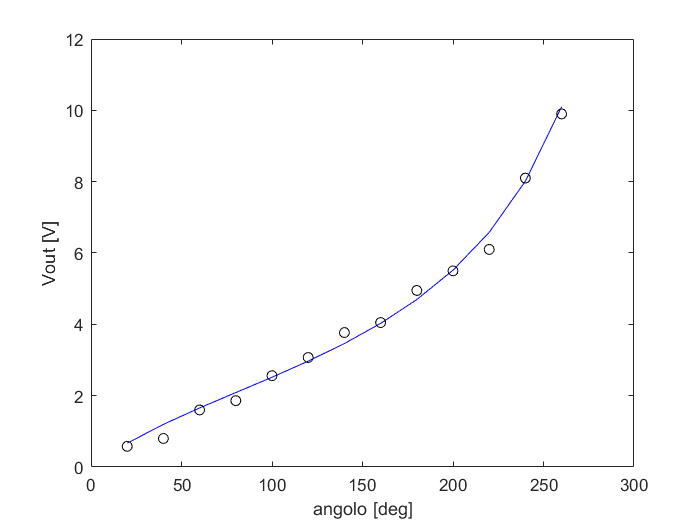



% plotto
Vest = (V0 * theta/L) ./(1 + k * theta/L .* (1-theta/L));

figure
plot(theta, Vest, '-b');
hold on
plot(theta, y, 'ok');
hold off
xlabel('angolo [deg]');
ylabel('Vout [V]');

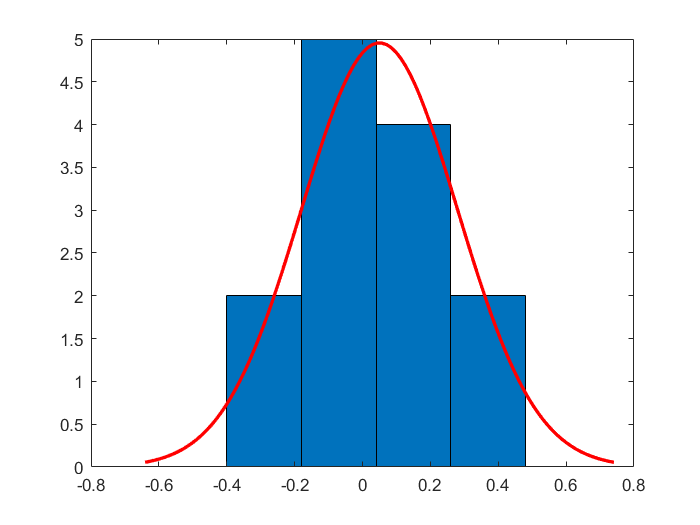


% calcolo dei residui
r = (V0 * theta/L) ./(1+k*theta/L.*(1-theta/L))- y;

figure
histfit(r);

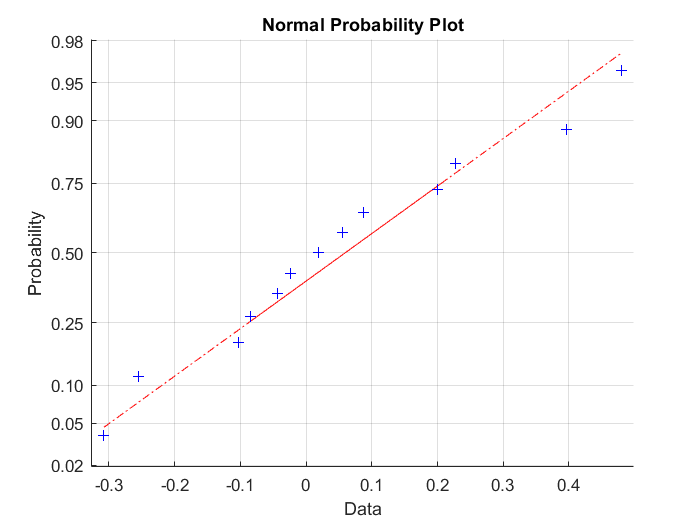


figure
normplot(r);